# Linear Control Design II - Group Work Problem Module 7 

                Roberto Galeazzi (2015), Hjalte Bested Møller (2017)

		        Department of Electrical Engineering 

                            Technical University of Denmark 

                                        August, 2017

## Description	

A system with three interconnected tanks is shown in Fig.1. The tanks have the cross sectional areas $A_1$, $A_2$ and $A_3$. The input flows are proportional to the input voltages, that is


$$q_a = k u_1$$



$$q_b = k u_2$$


The flows follow the square root law and since the pressures in the bottoms of the tanks are proportional to the level, one has 


$$q_1 = c_1 \sqrt{x_1-x_2}$$



$$q_2 = c_2 \sqrt{x3-x2}$$



$$q_0 = c_0 \sqrt{x_2}$$


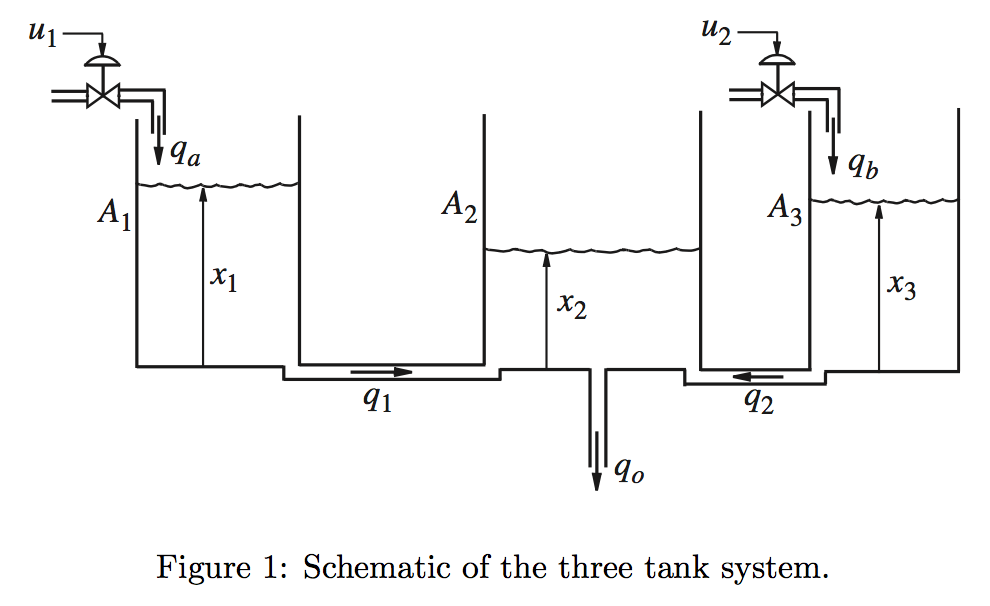				

**Problem 1**  Derive the set of equations describing the system and formulate the nonlinear state model with the two inputs $u_1$ and $u_2$, and the output = $q_0$. 

% Your solution goes here:




**Problem 2**  Find the stationary point under the assumption that the inputs are $u_1 = u_{10}$ and $u_2 = u_{20}$. 					

% Your solution goes here:




**Problem 3**  Linearize the model and derive the linear state space model

            Process equation:  $\Delta \dot{\mathbf{x}} =\mathbf{A} \Delta \mathbf{x} + \mathbf{B} \Delta \mathbf{u}$

            Output equation:    $\Delta \mathbf{y} = \mathbf{C} \Delta \mathbf{x}$

% Your solution goes here:




Table 1 shows the numerical value of the system’s parameters. The working interval of the input voltages $u_1$ and $u_2$ is 0-10 volts. 

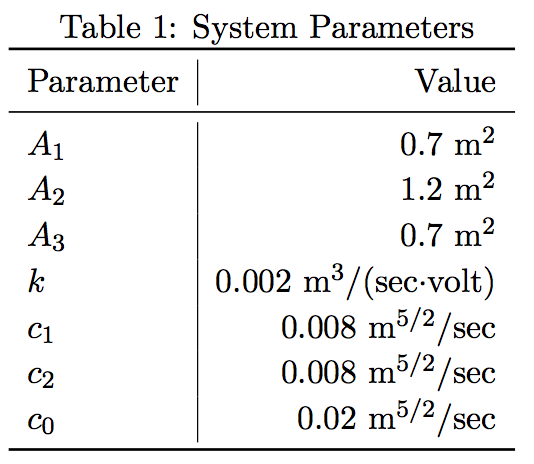

**Problem 4 ** Set up a Simulink model of the nonlinear system and write a MatLab script to initialize the model with the needed parameter values. Remember that all input variables must be provided with an in port, and all output variables must be provided with an out port in the model. 

% Define System parameters:
A1 = 0.7;
A2 = 1.2;
A3 = 0.7; 

k = .002; 

c1 = .008; 
c2 = .008;
c0 = .02;

% Your solution goes here:




**Problem 5**  Linearize the model using linmod. Set both inputs $u_1 = u_2 = 5$ volts. Simulink by default determine the numbering of the states in the model when linmod is used. It can be a little confusing when comparing Simulinks results with those obtained by manual calculations. If desired, one can determine one’s own numbering in the following way: 

- Choose an integrator in the model and do a right-button click 

- Choose Block Properties. A window opens

- Write the number desired in the Priority-field

- Close the Block Properties window 

% Your solution goes here:




**Problem 6 ** Simulate the nonlinear and linearized model for small and large variations of the system’s inputs $u_1$ and $u_2$ around their stationary values. Plot the state and output responses and try to determine which is the range of input variations where the linearized model is a good approximation of the nonlinear system. 

% Your solution goes here:




**Problem 7**  Determine the transfer functions from u1 to y and from u2 to y. 

% Your solution goes here:




**Problem 8**  Assess the internal and external stability of the system. 

% Your solution goes here:




**Problem 9**  Expand the Matlab script to compute the eigenvalues of the linearized system for input values in the entire interval 0-10 volts. Analyse the behaviour of the system eigenvalues as function of the operating point of the system. Hint: Include a for-loop which will find the stationary states by simulation over 5000 seconds for each value of $u$ (use the MATLAB function sim to simulate the system within the for-loop). Then linearize the model for each value using the final states (xFinal) as the stationary values. 

% Your solution goes here:




**Problem 10**  Choose a suitable sampling time $T_s$ and discretize the system obtained in Problem 5 using the Matlab$\mathtt{c2d}$-function. Calculate the eigenvalues of the discretized system both using the Matlab $\mathtt{eig}$-function and Frobenius theorem. Compare the obtained results. Is the discretization changing the stability properties of the system? 

% Your solution goes here:


